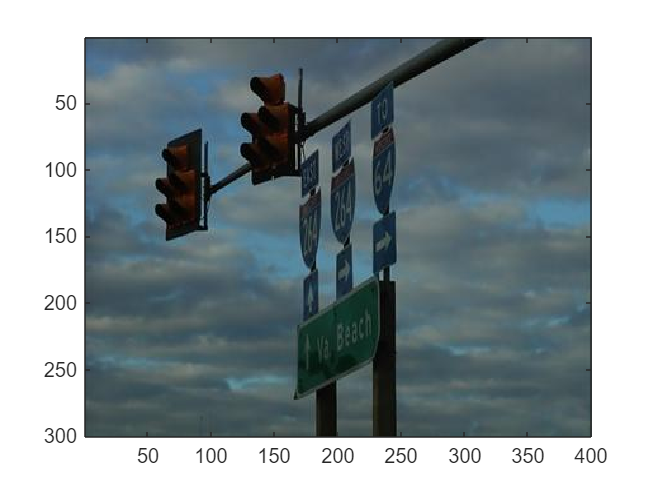

clear
addpath("Codes/Matlab");

c0=1;c1=1;c2=1;c3=1;
A = [ 1      c0          c1;
      c2    1+c0*c2    c1*c2;
      c3 c0*c1*c2*c3 1+c1*c3];
M = 256;

f = 3.6;
d_0 = 0.5;

alpha = 0.04;
beta = 0.02;

I = imread("Images/test_images/feu.jpg");
W = imread("Images/test_images/feuW.jpg");
Mask = imread("Images/test_images/water.jpg")/255;

[a,b,c] = size(I);



[F_I,B_I] = separation(I,Mask);
[F_W,B_W] = separation(W,Mask);

F_W_arnold = arnold(F_W,A,M);
B_W_arnold = arnold(B_W,A,M);
% Arnaque 0 : M = 256 non 512

F_W_logistic = logistic_map(F_W_arnold,Mask,d_0,f,false);
B_W_logistic = logistic_map(B_W_arnold,1-Mask,d_0,f,false);

F_final = apply_haar(F_I, F_W_logistic, alpha);
B_final = apply_haar(B_I, B_W_logistic, beta);

I_prime = fusion(F_final,B_final,Mask);
% Arnaque 1 : Je n'ai pas une image uint8 à la fin du tatouage
% cause : mes données ne sont pas en int


% -----------------------------------


[F_Iw,B_Iw] = separation(I_prime,Mask);
% Arnaque 2 : Mais on s'en fout de l'arnaque 1 car au final je n'utilise
% pas cette séparation dans la suite
% cause : F_final et F_iW ne sont pas =, leur différence est sur la "ligne
% du masque"


F_W_logistic_recover = reverse_haar(F_I, F_final, F_W_logistic, alpha);
B_W_logistic_recover = reverse_haar(B_I, B_final, B_W_logistic, beta);
% Arnaque 3 : J'utilise F_W_logistic pour retrouver F_W_logistic...
% cause : Car on a besoin des HL LH HH qu'on a pas sinon....


F_W_arnold_recover = logistic_map(F_W_logistic_recover,Mask,d_0,f,true);
B_W_arnold_recover = logistic_map(B_W_logistic_recover,1-Mask,d_0,f,true);

F_W_recover = arnold(F_W_arnold_recover,inv(A),M);
B_W_recover = arnold(B_W_arnold_recover,inv(A),M);

W_prime = fusion(F_W_recover,B_W_recover,Mask);

imagesc(uint8(I_prime));

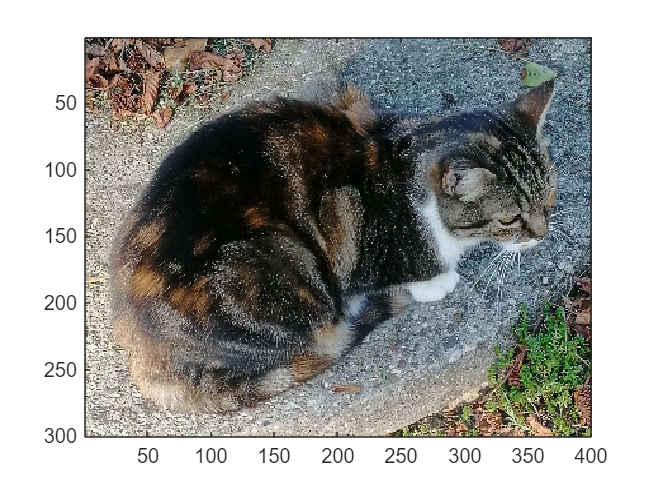

imagesc(uint8(W_prime));


ssim(uint8(W_prime),uint8(W))

ans = 1